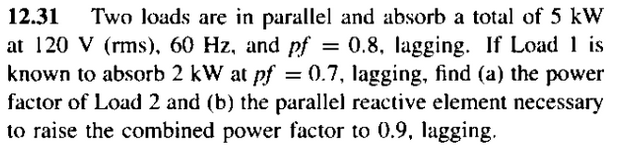

clc, clear, close all
format short g

vf = 120;
pt = 5e3;
pft = 0.8;

p1 = 4e3;
p2 = 3e3;

fp1 = 0.8;


calculamos la potencia reactiva de la carga 1:

q1 = p1*tan(acos(fp1)) %como es fp en atraso, sabemos que es una carga inductiva

q1 =          3000


s1 = p1 + j*q1 %potencia compleja en la carga 1

s1 =          4000 +       3000i


potencia compleja entregada por la fuente

qf = pt*tan(acos(pft))

qf =          3750


sf = pt + j*qf %potencia compleja en la fuente

sf =          5000 +       3750i


potencia compleja en la carga 2:

s2 = sf-s1

s2 =          1000 +        750i


factor de potencia en la carga 2:

fp2 = (real(s2)/abs(s2))

fp2 =           0.8


calculamos capacitancia para fp 1:

f = 60;
w = 2*pi*f;

xc = ((vf^2)/pt)/(tan(acos(0.9))-tan(acos(pft)));
c = -1/(w*xc)

c =     0.0002447
